# Problema 5

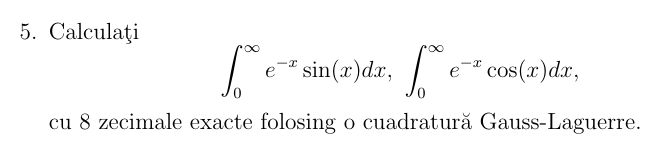

% PB1
function [noduri, coeficienti] = gauss_laguerre(n)
    alpha = zeros(n, 1);
    beta = sqrt((1:n-1)');  
    beta0 = 1;

    J = diag(alpha) + diag(beta, 1) + diag(beta, -1);
    [V, D] = eig(J);
    noduri = diag(D);
    [noduri, ord] = sort(noduri);
    V = V(:, ord);
    coeficienti = beta0 * V(1,:).^2;
end

function [I, I_ex, eroare] = integrare_laguerre(f, n, a, b, precizie)
% Input:
%   f        - functia f(x) fara pondere
%   n        - numarul de noduri
%   a, b     - capetele integralei (implicit: [0, ∞))
%   precizie - optional, precizia pentru comparatie numerica
%
% Output:
%   I        - valoare aproximata a integralei
%   I_ex     - valoare exacta calculata numeric
%   eroare   - eroare absoluta

    if nargin < 3, a = 0; end
    if nargin < 4, b = Inf; end
    if nargin < 5, precizie = NaN; end

    [x, A] = gauss_laguerre(n);

    if a == 0 && isinf(b)
        % Intervalul nativ pentru Gauss-Laguerre: [0, ∞)
        I = sum(A .* f(x));
    else
        % Daca intervalul nu este [0, ∞), aplicam schimbare de variabila:
        % x = (t - a) / (b - a), dar aici nu este cazul; putem avertiza
        warning("Gauss-Laguerre este destinat integrarii pe [0, ∞). Capetele [a, b] se ignora.");
        I = sum(A .* f(x));
    end

    % Integrare numerica pentru comparatie
    if isnan(precizie)
        I_ex = NaN;
        eroare = NaN;
    else
        integrand = @(x) f(x) .* exp(-x);
        I_ex = integral(integrand, a, b, 'RelTol', precizie);
        eroare = abs(I - I_ex);
    end
end

% Functii f(x), fara ponderea e^{-x}
f1 = @(x) sin(x);
f2 = @(x) cos(x);

n = 20;
a = 0; 
b = Inf;
eps = 1e-12;

[I1, Iex1, err1] = integrare_laguerre(f1, n, a, b, eps);
[I2, Iex2, err2] = integrare_laguerre(f2, n, a, b, eps);

fprintf(" Cuadratura Gauss-Laguerre cu n = %d noduri pe [%g, ∞)\n", n, a);

 Cuadratura Gauss-Laguerre cu n = 20 noduri pe [0, ∞)


fprintf("→ ∫₀^∞ e^{-x} sin(x) dx ≈ %.10f   (exact: %.10f)   | eroare: %.2e\n", I1, Iex1, err1);

→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -5.29e-23
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -1.73e-18
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -2.22e-16
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -1.67e-16
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -1.95e-18
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -5.29e-23
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} sin(x) dx ≈ 0.5000000000   (exact: 0.5000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} sin(x) dx ≈ 0.5000000000   (exact: 0.5000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} sin(x) dx ≈ 0.5000000000   (exact: 0.5000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} sin(x) dx ≈ 0.5000000000   (exact: 0.5000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} sin(x) dx ≈ 0.5000000000   (exact: 0.50000

fprintf("→ ∫₀^∞ e^{-x} cos(x) dx ≈ %.10f   (exact: %.10f)   | eroare: %.2e\n", I2, Iex2, err2);

→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0000000000   (exact: 0.0000000004)   | eroare: 9.71e-08
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0000069739   (exact: 0.0002040888)   | eroare: 2.90e-03
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0221756130   (exact: 0.0974394443)   | eroare: 2.56e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.4131528218   (exact: 0.4131528218)   | eroare: 2.56e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0974394443   (exact: 0.0221756130)   | eroare: 2.90e-03
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0002040888   (exact: 0.0000069739)   | eroare: 9.71e-08
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0000000004   (exact: 0.0000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.5000000000   (exact: 0.4999999996)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.4999930261   (exact: 0.4997959112)   | eroare: 4.97e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.4778243870   (exact: 0.4025605557)   | eroare: 2.44e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0868471782   (exact: 0.0868471782)   | eroare: 2.44e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.4025605557   (exact: 0.4778243870)   | eroare: 4